Universidad de Costa Rica

Maestría de Computación e Informática

Elaborado por Ruth Campos

Fecha: 28/08/2024

Ejercicios en Clase 3:  Notas

rotmx(0.3) % matriz de rotacion

ans =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553


q = quaternion(rotmx(0.3),"rotmat","point")

q = quaternion
     0.98877 + 0.14944i +       0j +       0k


q = q*q

q = quaternion
     0.95534 + 0.29552i +       0j +       0k


% la norma es un valor unitario
norm(q)

ans = 1.0000

norm(q*q)

ans = 1.0000

q.conj

ans = quaternion
     0.95534 - 0.29552i +       0j +       0k


qI = q*q.conj()

qI = quaternion
     1 + 0i + 0j + 0k


q.rotmat("point")

ans =     1.0000         0         0
         0    0.8253   -0.5646
         0    0.5646    0.8253


q.compact()

ans =     0.9553    0.2955         0         0


q.rotatepoint([0 1 0])

ans =          0    0.8253    0.5646


rotmx(0.001)

ans =     1.0000         0         0
         0    1.0000   -0.0010
         0    0.0010    1.0000


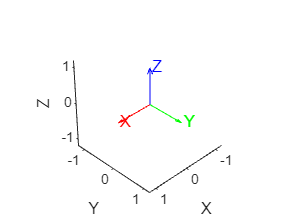

h =   Transform with properties:

    Children: [7×1 Graphics]
     Visible: on
     HitTest: on
      Matrix: [4×4 double]

  Show all properties


Rexact = eye(3); Rapprox = eye(3);  % null rotation
w = [1 0 0]';   % rotation of 1rad/s about x-axis
dt = 0.01;      % time step sec
tic
h = plottform(Rexact)

for i = 1:100     % exact integration over 100 time steps
  Rexact = Rexact*expm(vec2skew(w*dt));       % update by composition
  % plottform(Rexact, handle=h)
  % pause(0.1)
end
toc  % display the execution time

Elapsed time is 0.298927 seconds.


tic
for i = 1:100     % approximate integration over 100 time steps
  Rapprox = Rapprox + Rapprox*vec2skew(w*dt); % update by addition
end
toc  % display the execution time

Elapsed time is 0.002899 seconds.


det(Rapprox)-1

ans = 0.0100

det(Rexact)-1

ans = -2.5535e-15

rotm2axang(tformnorm(Rexact))

ans =      1     0     0     1


rotm2axang(tformnorm(Rapprox))

ans =     1.0000         0         0    1.0000
